# Threshold VAR



clear
close all
rehash path


addpath ../sandbox
addpath ../bear


## Convenience functions

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];


## Prepare data and a reduced-form model

inputTbx = tablex.fromCsv("threshold_data.csv");

estimStart = datex.q(1948,2);
estimEnd = datex.q(2016,4);
estimSpan = datex.span(estimStart, estimEnd);

meta = threshold.Meta( ...
    endogenous=["dl_y",	"dl_cpi", "ir_tb", "stock_index"], ...
    thresholdVarName="stock_index", ...
    units="", ...
    exogenous=[], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    ...
    identificationHorizon=20, ...
    shockConcepts=[] ...
);

dataH = threshold.DataHolder(meta, inputTbx);


## Minnesota dummies


minnesotaD = dummies.Minnesota();
minnesotaD

minnesotaD =   Minnesota with properties:

             Lambda: 0.1000
           LagDecay: 1
    ExogenousLambda: 100
     Autoregression: 0.8000
          Exogenous: 0



estimatorR = estimator.Threshold(meta);

modelR = threshold.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR ...
    , dummies={minnesotaD} ...
    , stabilityThreshold=Inf ...
);

modelR.Estimator.Settings

ans =   Threshold with properties:

              VarThreshold: 10
                  MaxDelay: 4
          ThresholdPropStd: 0.0316
                    Burnin: 0
                 Exogenous: [4×1 logical]
            BlockExogenous: 0
            Autoregression: [4×1 double]
                   Lambda1: 0.1000
                   Lambda2: 0.5000
                   Lambda3: 1
                   Lambda4: [4×1 double]
                   Lambda5: 1.0000e-03
        StabilityThreshold: Inf
    MaxNumUnstableAttempts: 1000


rng(0)
modelR.initialize();
info5 = modelR.presample(10000);


 Presampling threshold.ReducedForm (Threshold) [10000]
 ―――――――――――――――――――――――――――――――――――――――――――――――――◼  100% 



### Start forecast

setting up the sample

fcastStart1 = datex.shift(modelR.Meta.EstimationEnd, -15);
fcastEnd1 = datex.shift(modelR.Meta.EstimationEnd, -5);
fcastSpan1 = datex.span(fcastStart1, fcastEnd1);


Run forecast and show error band

fcastTbx1 = modelR.forecast(fcastSpan1);
fcastTbx1 = tablex.apply(fcastTbx1, prctileFunc);

fcastPrctileTbx1 = tablex.flatten(fcastTbx1);

fcastTbx1

fcastTbx1 = 11×8 timetable
     Time                  dl_y                                 dl_cpi                                   ir_tb                            stock_index             resid_dl_y     resid_dl_cpi    resid_ir_tb    resid_stock_index
    _______    _____________________________    ______________________________________    ___________________________________    _____________________________    ___________    ____________    ___________    _________________

    2013-Q1    0.76754     1.0516     1.3352       0.36211       0.51726       0.70395    -0.037056      0.17641      0.32484    0.86658    0.91466    0.97068    0    0    0    0    0    0     0   

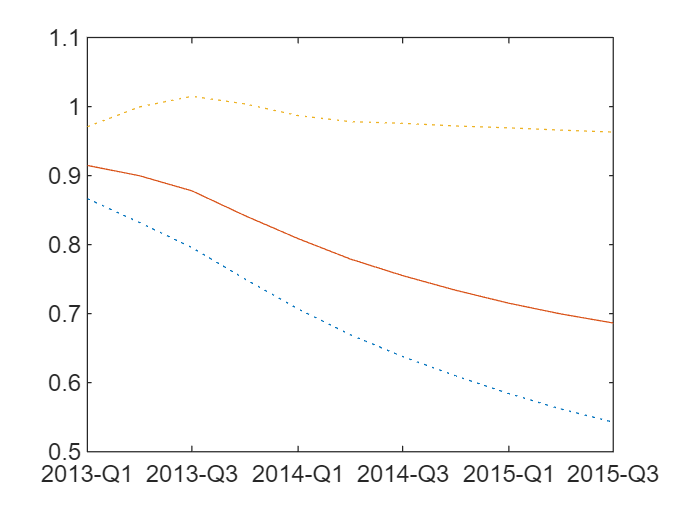


tablex.plot( ...
    fcastPrctileTbx1, "stock_index", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);